clear
syms s t tau

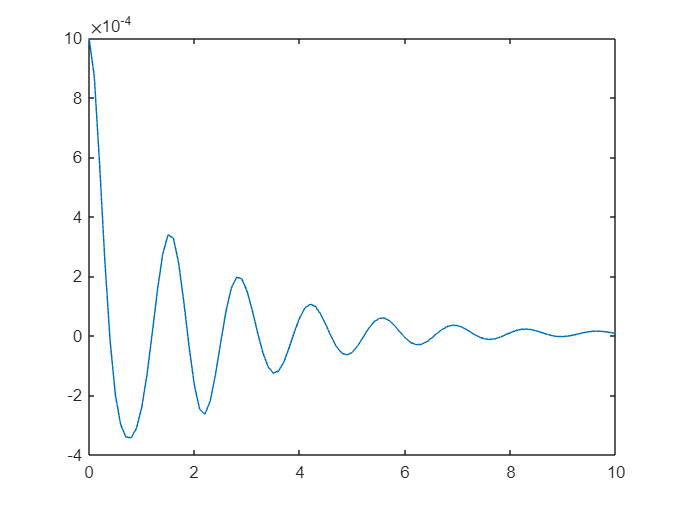

k1 = 150;
k2 = 700;
b1 = 15;
b2 = 3;
M1 = 5;
M2 = 20;

A = [0, 0, 1, 0;
    0, 0, 0, 1;
    -k1/M1, k1/M1, -b1/M1, b1/M1;
    k1/M2, -(k1+k2)/M2, b1/M2, -(b1+b2)/M2];
B=[0; 0; 1/M1; 0];
C=[0.001, 0, 0, 0]; % y(t) = p(t)
D= 0;
Phi = inv(s*eye(4)-A);
x0 = [1;0;0;0];
Phi_t = ilaplace(Phi,s,t);
Phi_tau = subs(Phi_t,t,t-tau);
Xt = Phi_t*x0+int(Phi_tau*B,tau,[0 t]);
y = C*Xt;
t_ = [0:0.1:10];
plot(t_,subs(y, t, t_))

sys = ss(A,B,C,D)

sys =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3    -30     30     -3      3
   x4    7.5  -42.5   0.75   -0.9
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
          x1     x2     x3     x4
   y1  0.001      0      0      0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


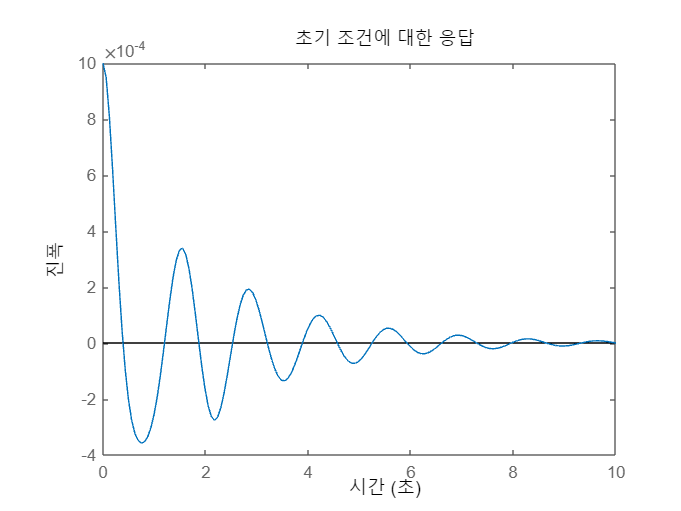

initial(sys,x0,10)